clear all;
close all;
clc;

***Operation levels***

H = 11000;     %Height (m)
M = 0.8;       %Machnumber

***Cycle parameters***

M_flow = 100;           %Mass flow (kg/s)
P_ratio = 25;           %Pressure ratio (P3Q2)
SOT = 1400;             %Statot Outlet Temperature (K)
Cp_e = 0.88;            %Compressor polytropic efficiency (%)
Tp_e = 0.89;            %Turbine polytropica efficiency (%)
C_e = 0.999;            %Combustion efficiency (%)
K_LHV = 43100;          %Kerosene fuel with LHV (kJ/kg)
M_e = 0.995;            %Mechanical efficiency (%)
IP_L = 0.005;           %Intake Pressure Loss (%)
Cefp_L = 0.02;          %Compressor exit diffuser pressure loss (%)
Cp_L = 0.03;            %Combustor pressure loss (%)
JpP_L = 0.01;           %Jet pipe Pressure loss (%)
P_n_CD = 0.97;          %Proppeling nozzle CD
P_n_CX = 0.99;          %Proppeling nozzle CX
Ase = 0;                %air system extractions

***Ambient conditions***

TAMB = 216.7            %Temperature ambient (K)
PAMB = 22.628           %Pressure ambient (kpa)

***Free stream condition***

y = 1.4;                %Gamma

Gamme waarde 1.4 is theoretisch, deze waarde kan gebruikt worden tot Mach 2.5, daarna moet deze waarde berekend worden.

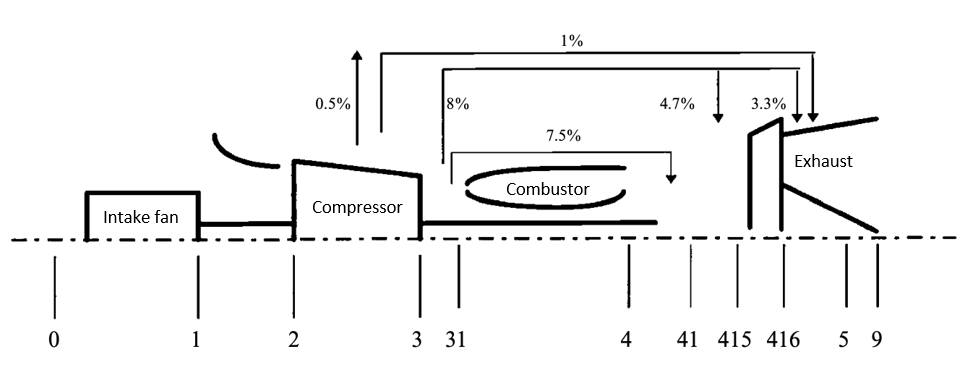

- 0:    Ram conditions in free stream

- 1:    Engine intake front flange/ leading edge 

- 2:    First compressor/ fan front face

- 3:    Last compressor exit face

- 4:    Combustor exit plane

- 5:    Last turbine exit face

- 6:    Front face of mixer, afterburner

- 7:    Propelling nozzle inlet

- 8:    Propelling nozzle thoat

- 9:    Propelling nozzle or exhaust diffuser exit plane

- 31:  Compressor outlet diffuser exit/combustor inlet 

- 41:  Stator outlet temperature 

T1 = TAMB*(1+(y-1)/2*M^2);      %Temperature after intake(K)
P1 = PAMB*((T1/TAMB)^3.5);      %Pressure after intake(kPa)

***Intake***

T2 = T1;                %Temperature at intake compressor
P2 = P1*(1-IP_L);       %Pressure at itnake compressor
W2 = M_flow;            %Mass flow before intake compressor

***Compressor***

Isentropic = all politropic efficiency together in 1 component.

ETA2 = (P_ratio^((y-1)/y)-1)/(P_ratio^((y-1)/(y*Cp_e))-1);    %Compressor isentropic efficiency 
T3 = (T2/ETA2*(P_ratio^((y-1)/y)-1)+T2);                      %Temperature after compressor
P3 = P2 * P_ratio;                                            %Pressure after compressor
W3 = W2;                                                      %Mass fow after compressor
CP = 1.005;                                                   %kJ/kg K is a constant
PW2 = W2 * CP * (T3-T2);                                      %Pressure mass flow before intake compressor
WTP = M_flow*T2^0.5/P2;

***Compressor exit diffuser***

T31 = T3;                   %Temperature before combuster
P31 = P3*(1-Cefp_L);        %Pressure los between compressor and combuster
W31 = W3;                   %Mass flow before combuster

***Combuster and SOT station***

T4 = SOT;                           %Temperature after combuster
P4 = P31*(1-Cp_L);                  %Pressure after combution
FAR = 1.15*(SOT-T31)/C_e/K_LHV;     %Fuel air ratio
WF = FAR * M_flow;                  %Fuel flow
W4 = W31 + WF;

***Turbine***

PW41 = PW2/M_e;                     %Pressure mass flow after combuster

